clear all;

path_2_wav = ['/Users/mathiaskroismoller/Library/Mobile Documents/com~apple~CloudDocs/Documents/DTU/7. Semester/DSP/Assingments/', filesep, 'Assingment 1', filesep];    % the path to the data
fname = 'iii.wav';                                 % a file name stored in a string variable

[y, fs_y] = audioread([path_2_wav, fname]);

% Convert times to sample indices
start_sample = round(2 * fs_y);
end_sample = round(2.5 * fs_y);

% Extract the portion of the audio between 2 and 3 seconds
y = y(start_sample:end_sample);

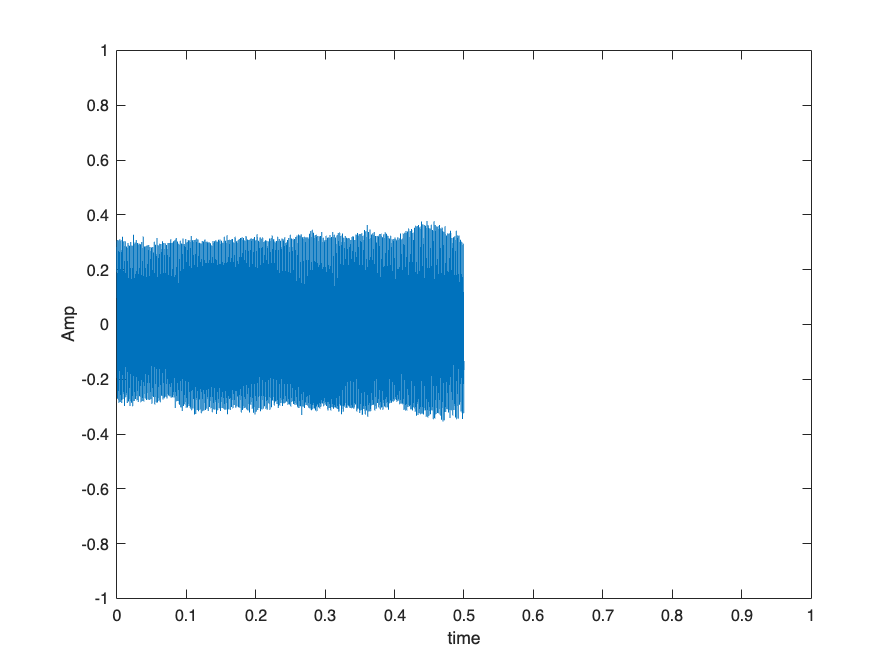

t = (0:length(y)-1)/fs_y;

figure('Name','A simple sinusoid')
plot(t,y,'-')

xlabel('time')              % labelling - please add
ylabel('Amp')

xmin = 0;
xmax = 1;   
ymin = -1;
ymax = 1;                       % please add

xlim([xmin, xmax])               % the limits as a vector
ylim([ymin, ymax])

% Perform FFT
n = length(y);                     % Number of samples
Y = fft(y);                        % Compute FFT
f = (0:n-1)*(fs_y/n);              % Frequency range
P = abs(Y)/n;                      % Compute magnitude of the FFT

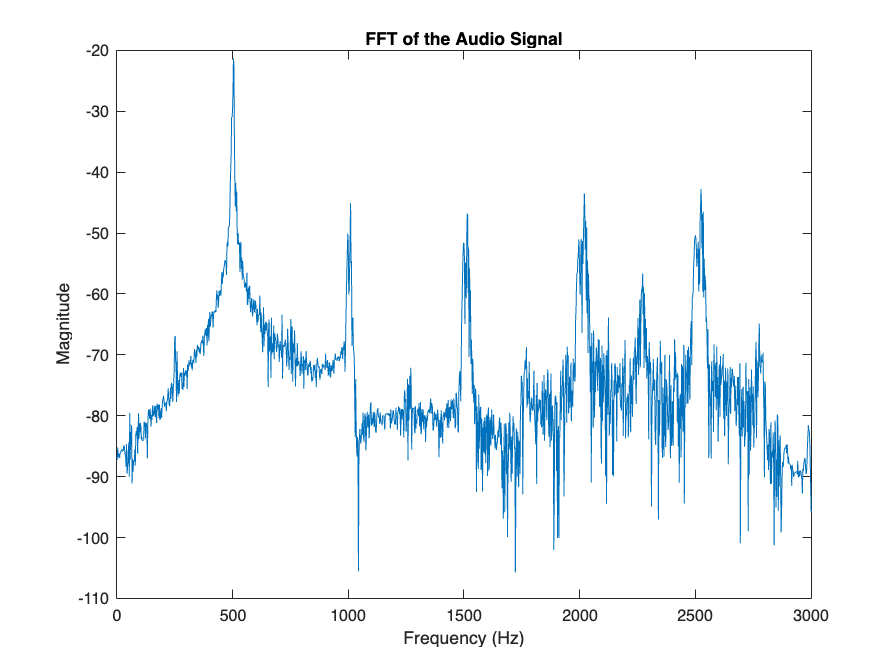

figure('Name','Frequency Spectrum')
plot(f, 20*log10(P))
xlim([0, 3000])
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT of the Audio Signal')

% Generate a 500 Hz sine wave (clean signal)
f_clean = 500;  
phase = pi/3

phase = 1.0472

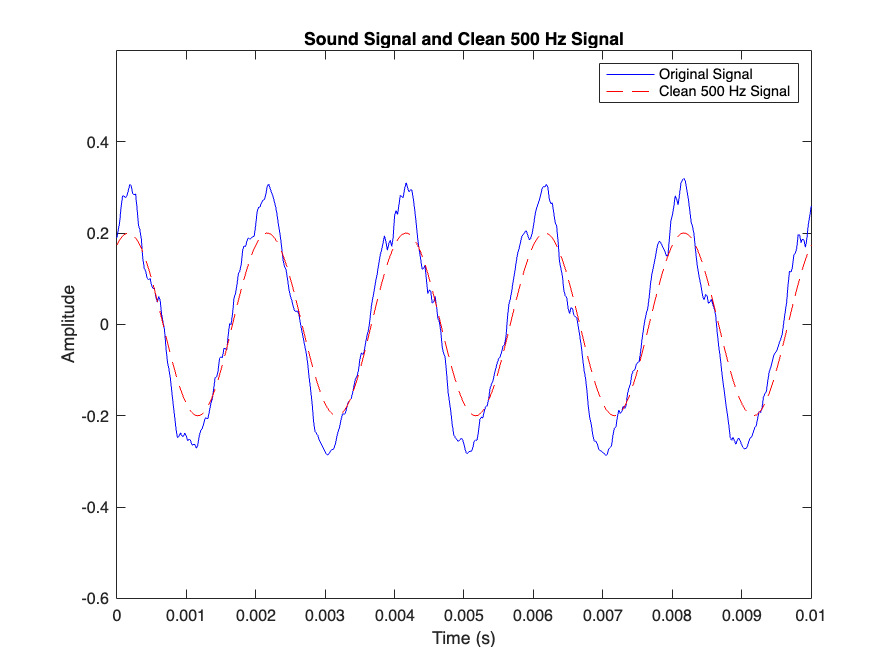

clean_signal = 0.2*sin(2*pi*f_clean*t+phase);  

% Plot the sound signal and the clean 500 Hz signal together
figure;
plot(t, y, 'b', 'DisplayName', 'Original Signal'); hold on;
plot(t, clean_signal, 'r--', 'DisplayName', 'Clean 500 Hz Signal');  % Plot clean signal in dashed red
title('Sound Signal and Clean 500 Hz Signal');
xlabel('Time (s)');
ylabel('Amplitude');
legend;
ylim([-0.6 0.6]);
xlim([0 0.01]);  % Limit x-axis to the signal's time range
hold off;

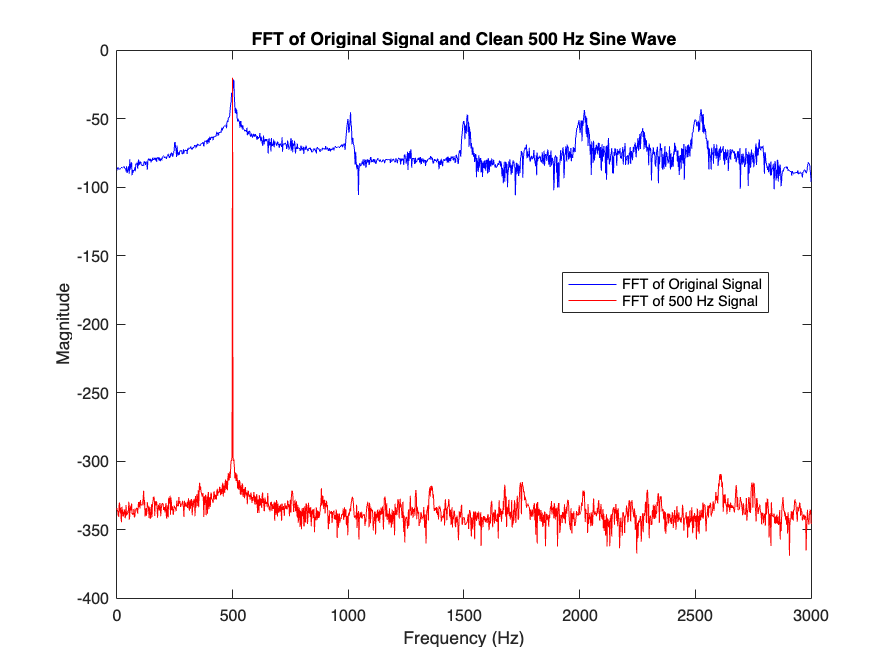

% FFT calculation for both signals with a resolution of 2 Hz
n = length(y);                   
f_res = 2;                       % Desired frequency resolution in Hz
N_fft = fs_y / f_res;              % FFT points to achieve 2 Hz resolution
f_clean = (0:N_fft-1)*(fs_y/N_fft);      % Frequency vector

% Compute FFT of the clean signal 
Y_clean = fft(clean_signal, N_fft);  
P_clean = abs(Y_clean)/n;                  

% Plot the FFTs together
figure;
plot(f, 20*log10(P), 'b', 'DisplayName', 'FFT of Original Signal'); hold on;
plot(f_clean, 20*log10(P_clean), 'r', 'DisplayName', 'FFT of 500 Hz Signal');  % Plot FFT of clean signal in dashed red
xlim([0 3000]);  % Plot up to 3000 Hz
title('FFT of Original Signal and Clean 500 Hz Sine Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend;
hold off;